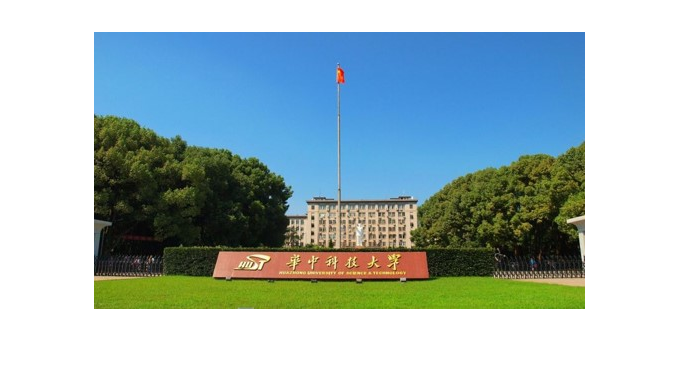

figure=imread('figure.jpg');
fig1=imshow(figure);

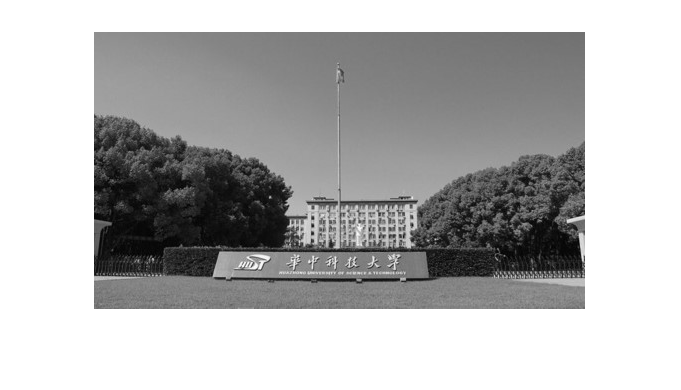

gray_fig=im2double(rgb2gray(figure));%不转成double的话就是uint8, 后续做傅里叶变换的时候会出错
fig2=imshow(gray_fig);

%matlab自带的fft2方法
tic
fft2_res=fft2(gray_fig);
toc

历时 0.061675 秒。


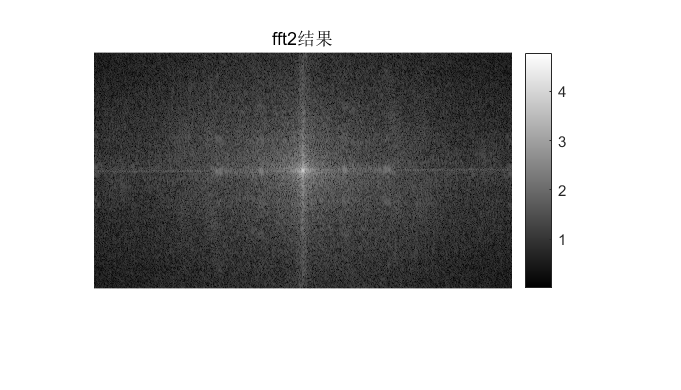

F=fftshift(fft2_res);%将频率原点移至中心点
imF=log10(abs(F)+1);
imshow(imF,[])%[]会把结果映射到01区间内
title('fft2结果')
colormap gray
colorbar

%我写的分离式二维dft
tic
my_res=ft2(gray_fig);
toc

历时 0.042696 秒。


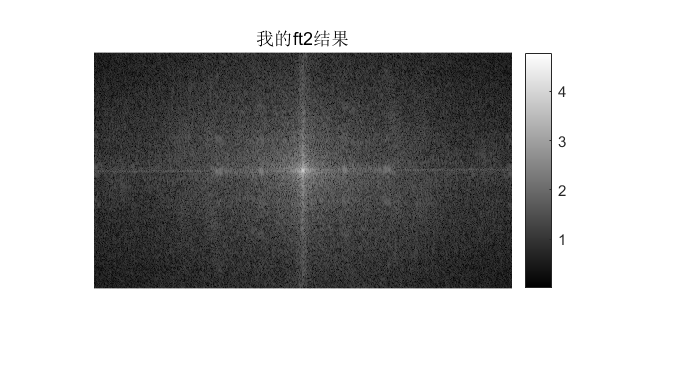

F=fftshift(my_res);%将频率原点移至中心点
imF=log10(abs(F)+1);
imshow(imF,[])%[]会把结果映射到01区间内
title('我的ft2结果')
colormap gray
colorbar

% 检查一下结果对不对
isequal(round(fft2_res,5),round(my_res,5))%考虑到小数精度问题, 所以只选择了前5位小数进行比较

ans = logical
   1
